This script uses analytical theory to fit experimental SAXS data of Polyimide-PEG random copolymers.

Load experiment data.

clear;
close all
addpath('functions/')
data = load('exp-data/PEG30undoped.csv');  % SAXS data with q in A^(-1)
                                           % 30wt ~= 16mol%
FA=0.165;    % chemical composition
alpha = 143.8532;  %intensity scaling
rm = 32.05; % estimate end-to-end distance of a "chemical monomer" in unit of Angstrom

TV = [22,40:20:180];  % temperature in degree C
TK = TV+273.15;       % temperature in Kelvin
q = data(:,1);
s = data(:,2:end);

Define a small q cutoff and estimate peak intensity S(q~=0).

% if PEG wt% = 0.30
qmin0 = 0.03803;
qminf = 0.04094;

iqmin0 = find(q==qmin0);
iqminf = find(q==qminf);
smin = mean(s(iqmin0:iqminf,:));
sminstd = std(1./s(iqmin0:iqminf,:));

Make a plot of structure factor.

figure;hold

Current plot held


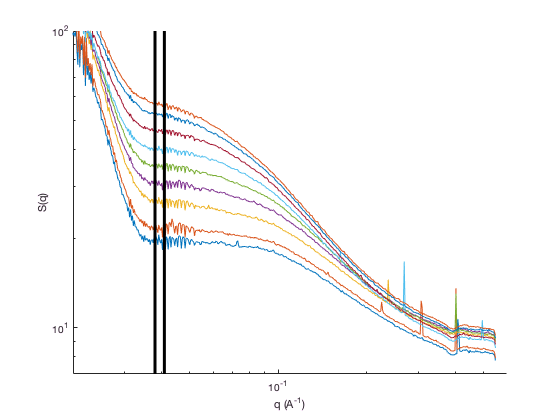

% at which temperature?
Trange=1:9;
for T=Trange
    plot(q,s(:,T));
end
plot([qmin0,qmin0],[7,1e2],'k-','linewidth',3)
plot([qminf,qminf],[7,1e2],'k-','linewidth',3)

xlabel('q (A^{-1})');ylabel('S(q)')
set(gca,'xscale','log');set(gca,'yscale','log');
xlim([0.02,0.6]);ylim([7,1e2]);

 Next plot temperature versus estimated inverse peak intensity. Theoretical estimate of ODT temperature is the x-intercept of the plot.

figure;hold;

Current plot held


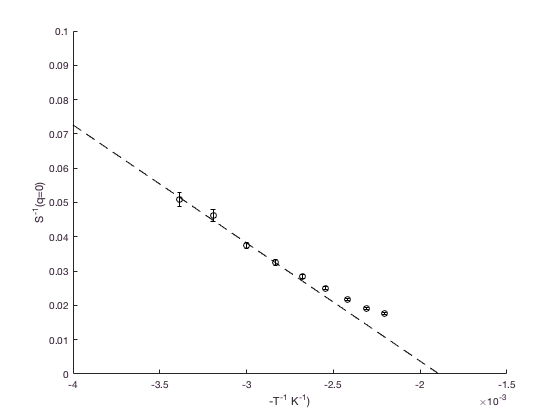

errorbar(-1./TK,1./smin,sminstd,'ko')
%negative sign in T to account for temperature effects on SAXS intensity (degree of phase segregation)
xlabel('-T^{-1} K^{-1})');ylabel('S^{-1}(q=0)')

% fit linear regression at q*=0
fit_range = 1:3;  % linear fit regime at low Temperature
x = -1./(TK(fit_range))';
y = 1./smin(fit_range)';

X = [ones(length(x),1) x];
b = X\y;
xp = linspace(-4,-1,100)*1e-3;
yp = b(2)*xp+b(1);
plot(xp,yp,'k--');
ylim([0,.1])

Fit using Smin.

1. Use one parameter fit (intensity scaling) to obtain prediction of CHI at T.

c=1/(FA*(1-FA));
slope = b(2);  %slope in S(q=0) fit
intcp = b(1);  %intercept in S(q=0) fit
m = (-1/2)*alpha*slope;
n = (-1/2)*(alpha*intcp-c);
figure;hold

Current plot held


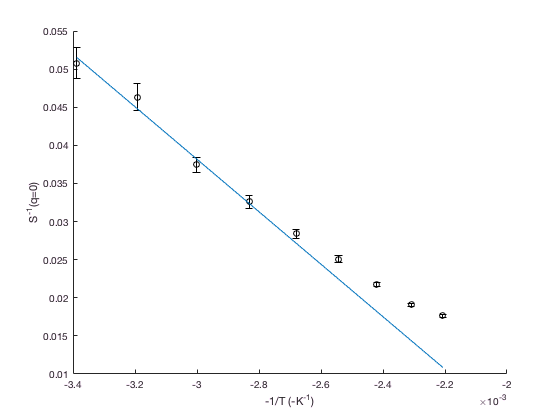

errorbar(-1./TK,1./smin,sminstd,'ko')
CHIF = m*(-1./TK)+n;
Smin = power(-2*CHIF+1/(FA*(1-FA)),-1);  % zero q analytical structure factor
plot(-1./TK,1./Smin/alpha)
xlabel('-1/T (-K^{-1})');ylabel('S^{-1}(q=0)')

% polymer parameters
N=100;  % total of 100 monomers
NM=0.1; % each monomer has 0.1 Kuhn steps
LAM=0.0; % ideal random copolymer

% length parameters
RM=sqrt(r2wlc(NM));  % end-to-end distance of a monomers
K0=1e-1;  % minimum wavevector
KF=1e2;   % maximum wavevector
NK=101;  % number of wavevectors
K=transpose(logspace(log10(K0),log10(KF),NK))/RM;

% calculate structure factor
[SINV]=s2invwlc(N,NM,FA,LAM,K);

CHIF = m*(-1./TK)+n;
CHIF(1)=0;
figure;hold

Current plot held


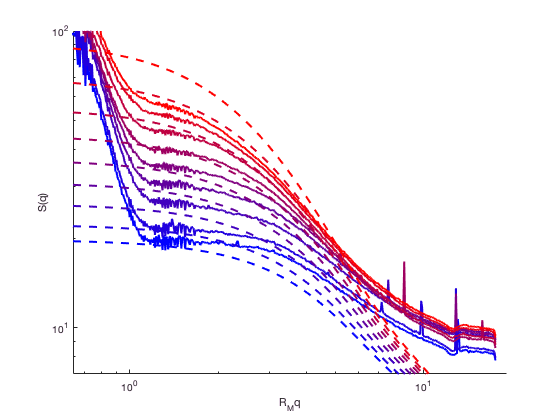

for T=Trange
    col = (T-1)/(length(Trange)-1);
    CHI=CHIF(T);
    plot(q*rm,s(:,T),'-','LineWidth',2,'color',[col 0 1-col])
    plot(RM*K,alpha./(-2*CHI+SINV*NM),'--','LineWidth',2,'color',[col 0 1-col])
%    qf = q(iqmin0:10:end);
%    plot(qf*rm,alpha./(-2*CHI+s2invwlc(N,NM,FA,LAM,qf*rm)*NM),'--','LineWidth',2,'color',[col 0 1-col])
end
set(gca,'xscale','log');set(gca,'yscale','log');
xlim([0.02,0.6]*rm);ylim([7,1e2]);
xlabel('R_Mq');ylabel('S(q)');

% % choose fitting range
% IT = 9;  % at which temperature
% qf = q(iqmin0:end);
% sf = s(iqmin0:end,IT);
% 
% % fit to structure factor
% x = [2.0686,200,374];  %initial fit guess, % x(1) = CHI, x(2) = intensity scale, x(3) = Rm
% x = [2.8483,200,374];  %initial fit guess, % x(1) = CHI, x(2) = intensity scale, x(3) = Rm
% Sfun = @(param,qfit) param(2)./(-2*param(1)+s2invwlc(N,NM,FA,LAM,qfit*param(3))*NM);
% sfit = Sfun(x,qf);
% 
% figure;hold;
% plot(q*x(3),s(:,IT),'k-','LineWidth',2) % experiment data
% plot(qf*x(3),sfit,'k--','LineWidth',2) % theoretical fit
% xlabel('R_Mq');ylabel('S(q)');title(strcat('T=',num2str(TK(IT)),'K'))
% set(gca,'xscale','log');set(gca,'yscale','log');
% xlim([0.02,0.6]*x(3));ylim([7,1e2]);